# 演習10-1 ２分法 bisect

非線形方程式f(x)=0の[0 1]区間の解を2分法(bisect)を使用して求める

•初期値a=0, b=1とする


$$f\left(x\right)=\cos \left(x\right)-x=0$$


•ファイル後部にある2分法のプログラムを完成させて使用する

% 2分法の呼び出し
a=0; b=1;
format longE;
[x, bi_data]=bisect(@f, a, b);
disp(x);

     7.390851332151600e-01



disp(bi_data);

     5.000000000000000e-01
     7.500000000000000e-01
     6.250000000000000e-01
     6.875000000000000e-01
     7.187500000000000e-01
     7.343750000000000e-01
     7.421875000000000e-01
     7.382812500000000e-01
     7.402343750000000e-01
     7.392578125000000e-01
     7.387695312500000e-01
     7.390136718750000e-01
     7.391357421875000e-01
     7.390747070312500e-01
     7.391052246093750e-01
     7.390899658203125e-01
     7.390823364257812e-01
     7.390861511230469e-01
     7.390842437744141e-01
     7.390851974487305e-01
     7.390847206115723e-01
     7.390849590301514e-01
     7.390850782394409e-01
     7.390851378440857e-01
     7.390851080417633e-01
     7.390851229429245e-01
     7.390851303935051e-01
     7.390851341187954e-01
     7.390851322561502e-01
     7.390851331874728e-01
     7.390851336531341e-01
     7.390851334203035e-01
     7.390851333038881e-01
     7.390851332456805e-01
     7.390851332165767e-01
     7.390851332020247e-01
     7.390851332093007e-01
 

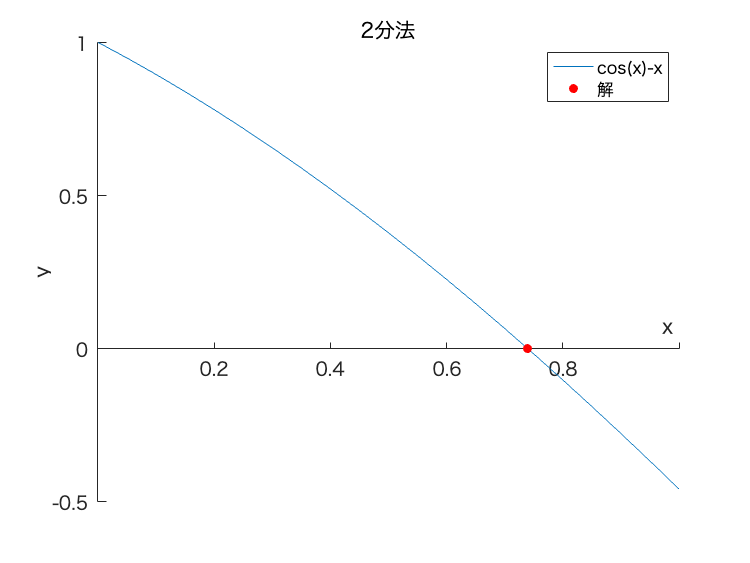

% グラフ作成
clf
hold on;
xdata=0:0.05:1;
ydata=f(xdata);

plot(xdata,ydata);                  % 非線形関数のグラフ
plot(x,f(x),'r.','markersize',20);  % 解のプロット

graph = gca();
graph.FontSize =14;
graph.XAxisLocation = "origin";  % x軸の場所指定
xlabel('x');    % x軸ラベル
ylabel('y');    % y軸ラベル
title('2分法');
legend('cos(x)-x', '解');
hold off;

# 演習10-2 ニュートン法 (1)

•非線形方程式　　$f\left(x\right)=x^2 -a=0$

•方程式の解  　x=√a　

•ニュートン法の漸化式$x_{k+1} =x_k -\frac{f\left(x_k \right)}{f^{\prime } \left(x_k \right)}$を整理する

•a=2，初期値x=1として漸化式を数回適用して，√2に収束することを確認する

format long
x=2.0

x =      2



% 漸化式で計算
% 
% 
% 2に収束することを確認
x*x

ans =      4


# 演習10-3 二分法とニュートン法の収束比較

•ファイル後部にあるニュートン法(newton)のプログラムを完成させなさい

•二分法とニュートン法を用いて，非線形方程式の解の収束状況を比較する


•非線形方程式f(x)=0の[0 1]区間の解を求める

•初期値a=0.0とするが，うまく収束したら別の初期値 a=4.0でも試す


$$\begin{array}{l}
f\left(x\right)=\cos \left(x\right)-x=0\\
\frac{\textrm{df}}{\textrm{dx}}=-\sin \left(x\right)-1
\end{array}$$


% ニュートン法の呼び出し
a=5.0;
format longE;
[x, nt_data]=newton(@f, @df, a);
disp(x);

     7.390851332151607e-01



disp(nt_data);

    -1.098205607048480e+02
     1.596077756108207e+01
    -6.615115461729538e+00
     4.600099704729104e+00
    -7.436197251930475e+02
     3.090758390637214e+03
    -3.606140072709170e+03
    -1.024218222632347e+03
     6.525924351212780e+01
     2.537146766470165e+01
     5.637936679512165e+00
    -6.501930818896746e+00
     3.048708935724070e+00
    -6.524098343970368e-01
     3.030573762992783e+00
    -5.924458502207326e-01
     2.627655112660294e+00
     2.822224409276082e-01
     8.127044843596625e-01
     7.401919868851872e-01
     7.390854034153619e-01
     7.390851332151768e-01
     7.390851332151607e-01
     7.390851332151607e-01



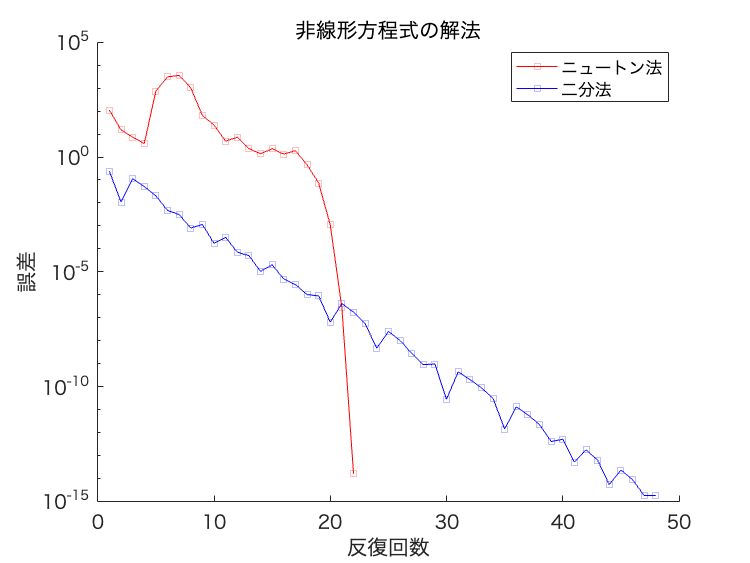


% ニュートン法と２分法の比較グラフ
%
clf
hold on;                            % 2つのグラフを重ね書きする
nnt=size(nt_data,1);                % nt_data ニュートン法の近似値配列
nbi=size(bi_data,1);                % bi_data 二分法の近似値配列
nt_true=nt_data(nnt);               % ニュートン法の真値（収束値）
bi_true=bi_data(nbi);               % 二分法の真値（収束値）
nt_error=abs(nt_data-nt_true);      % ニュートン法の誤差配列
bi_error=abs(bi_data-bi_true);      % 二分法の誤差配列
plot(1:nnt,nt_error(1:nnt),'r-s');  % ニュートン法は赤色(r);
plot(1:nbi,bi_error(1:nbi),'b-s');  % 二分法は青色(b);

% グラフの修飾
xlabel('反復回数');    % x軸ラベル
ylabel('誤差');        % y軸ラベル
graph = gca;            % グラフのハンドルを取得
graph.FontSize =14;
graph.YScale='log';       % y軸対数スケールの設定
graph.XScale='linear';    % x軸対数スケールの設定
legend('ニュートン法','二分法');
title('非線形方程式の解法');
hold off;

# 演習10-4 割線法 secant

•非線形方程式f(x)=0の解を割線法(secant)を使用して求める

•ファイル最後部にある割線法のプログラムを完成させなさい

•方程式および初期値については演習10-3と同じとする


% 割線法の呼び出し
% 非線形方程式f(x)=0と初期値a,bを定義して呼び出す
a=0.0;
format longE;
[x, sc_data]=secant(@f, a, b);
disp(x);

     7.390851332151607e-01



disp(sc_data);

     6.850733573260451e-01
     7.362989976136540e-01
     7.391193619116293e-01
     7.390851121274639e-01
     7.390851332150012e-01
     7.390851332151607e-01
     7.390851332151607e-01



# 参考　 MATLABの組込み関数fsolve

•下記の非線形方程式の[0 1]区間の解をfsolceを使用して求める

•初期値a=0とする


$$f\left(x\right)=\cos \left(x\right)-x=0$$



% fsolveの呼び出し
a=0;
format longE;
fs_true=fsolve(@f,a)

'fsolve' には Optimization Toolbox が必要です。

# ファイルの最後に関数定義を記述

対象となる非線形方程式

function y = f(x)
%　非線形方程式 f(x) = 0
y = cos(x)-x;
end

function y = df(x)
%　 f(x) の一次導関数
y = -sin(x)-1;
end

2分法，ニュートン法，割線法

function [x, bi_data] = bisect(f, a, b)
% 2分法
% 解x，収束データbi_data, 関数f(x), 区間a, b
% f(a)<=0<=f(b)になるよう交換
if f(a)>0 && f(b)<0
    c=a; a=b; b=c;
end
eps=1.0e-15; %eps; % 要求精度
% 反復回数
n=ceil(log2(abs(b-a)/eps))-1;
bi_data=zeros(n,1);
% ２分反復
for k=1:n
    c=(a+b)/2;
    % if文を使って，aまたはbを更新
    % 穴埋め
    if (f(c)>0)
        b=c;
    else
        a=c;
    end
    % 穴埋め
    bi_data(k,1)=c; %　途中データを記録
end
% 収束データ
x=(a+b)/2; % 最終区間の中点
end

function [x, nt_data] = newton(f, df, a)
% ニュートン法
% 解x，収束データnt_data, 関数f(x), 導関数df(x), 初期値　a
% 要求精度, 最大反復回数
eps=1.0e-15;   kmax=100;
nt_data=zeros(1,1);
% 初期値
x=a;
% 反復計算
for k=1:kmax
    % ニュートン法の反復式を使う
    % 穴埋め
    dx=-f(x)/df(x);
    x=x+dx;
    % 穴埋め
    % 収束データ
    nt_data(k,1)=x;
    if abs(dx) <= eps
        break
    end
end
end

function [x1, sc_data] = secant(f, a, b)
% 割線法
% 解x1，収束データsc_data, 関数f(x), 初期値　a,b
% 要求精度, 最大反復回数
eps=1.0e-15;   kmax=100;
sc_data=zeros(1,1);
%初期値
x0=a;
x1=b;
dx=x1-x0;
y0=f(x0);
%反復計算
for k=1:kmax
    y1=f(x1);
    dx=dx*(-y1/(y1-y0));
    x1=x1+dx;
    y0=y1;
    %データ
    sc_data(k,1)=x1;
    if abs(dx) <=eps
        break
    end
end
%
%
%
end
